# A step-by-step guide to parsimoneous enzyme usage Flux Balance Analysis - pFBA

**Author(s): Francisco José Pardo Palacios, Ines Thiele, LCSB, University of Luxembourg.**

**Reviewer(s): Sebastián Mendoza, Center for Mathematical Modeling, University of Chile. Catherine Clancy, LCSB, University of Luxembourg.**

**Lin Wang (Costas D. Maranas Lab), Joshua Chan (Costas D. Maranas Lab), Chiam Yu Ng (Costas D. Maranas Lab)**

## INTRODUCTION

This tutorial shows how the parsimoneous enzyme usage Flux Balance Analysis (pFBA), as described in Lewis et al.$$^1$, has been implemented in The COBRA Toolbox as the function `pFBA()`.

The main aim of the tutorial is to explain how the calculations are carried out in order to understand the pFBA analysis, and to be able to classify, under certain conditions, the genes of a model as: essential, pFBA optima, Enzymatically Less Efficient (ELE), Metabolically Less Efficient (MLE) or pFBA no-flux genes (Figure 1). 

- ***Essential genes:*** metabolic genes necessary for growth in the given media.

- ***pFBA optima: ***non-essential genes contributing to the optimal growth rate and minimum gene-associated flux.

- ***Enzymatically less efficient (ELE): ***genes requiring more flux through enzymatic steps than alternative pathways that meet the same predicted growth rate.

- ***Metabolically less efficient (MLE):*** genes requiring a growth rate reduction if used.

- ***pFBA no-flux:*** genes that are unable to carry flux in the experimental conditions.

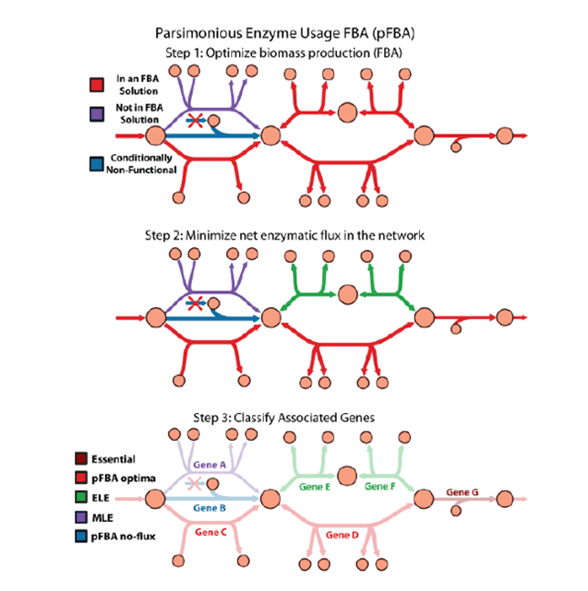

                                                                                 Figure 1: Gene/enzyme classification scheme used by pFBA

This tutorial will use the* E. coli core *reconstruction$$^2$ as the model of choice, and will be called herein as `modelEcore`. The results obtained could then be compared to data from evolved E. coli and observe if the `modelEcore` can predict its evolution. In order to investigate this, all the steps described in the pFBA flowchart (Figure 2) should be followed, and are demonstrated in this tutorial. 

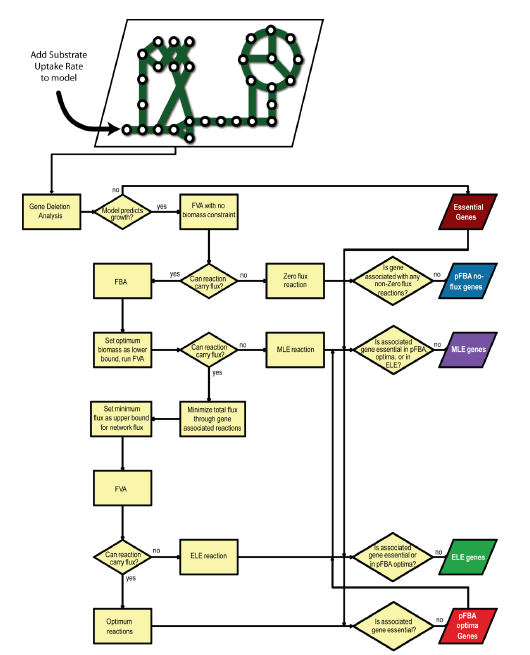

                                                                                                          Figure 2: pFBA flowchart

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

If necessary, initialize The Cobra Toolbox using the `initCobraToolbox` function.

%initCobraToolbox

## **Setting the **optimization** solver.**

This tutorial will be run with a `'glpk``'` package, which is a linear programming ('`LP'`) solver. The `'glpk``'` package does not require additional instalation and configuration.

solverName = 'glpk';
solverType = 'LP'; 
changeCobraSolver(solverName, solverType);
% changeCobraSolver('ibm_cplex');
% changeCobraSolver('gurobi');

However, for the analysis of larger models, such as Recon 2.04$$^3$, it is not recommended to use the `'glpk``'` package but rather an industrial strength solver, such as the `'gurobi' or 'ibm_cplex'` package.

A solver package may offer different types of optimization programmes to solve a problem. The above example used a LP optimization, other types of optimization programmes include; mixed-integer linear programming ('`MILP`'), quadratic programming ('`QP`'), and mixed-integer quadratic programming ('`MIQP`').

## **Model setup.**

Load the modelEcore, and define the uptake of nutrients by the modelEcore. The substrate used is glucose, and for this tutorial limit its uptake up to 18 mmol/(gDW·h).

modelFileName = 'ecoli_core_model.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);
model = changeRxnBounds(model, 'EX_glc(e)', -18, 'l');

## PROCEDURE

## Identify essentail reactions: perform a gene knocked-out analysis. 

If the modelEcore is not able to grow when a certain gene is knocked-out, the name of that gene will be saved as an essential gene. Even if a very small growth is calculated, the model will be considered as not growing and the gene will be recorded in an 'essential_genes' vector. Here no growth is defined as growth lower than 0.000001. The remaining non-essentail genes will be stored in a 'non_EG' vector.

[grRatio, grRateKO, grRateWT, delRxns,...
    hasEffect] = singleGeneDeletion(model, 'FBA', model.genes);
essential_genes = [];
non_EG = [];
tol = 1e-6;
for n = 1:length(grRateKO)
    if (grRateKO(n)<tol)||(isnan(grRateKO(n))==1)
        essential_genes = [essential_genes; model.genes(n)];
    else
        non_EG = [non_EG; n];
    end
end

% find essential reactions
RxnRatio = singleRxnDeletion(model);
RxnRatio(isnan(RxnRatio)) = 0;
pFBAEssentialRxns = model.rxns(RxnRatio < tol);

## Identify non-essentail reactions that can or cannot carry flux:

A FVA is performed without any biomass constraint. Therefore, for the `fluxVariability` function set the percentage of optimal solution to zero %. The reactions that do not carry flux will be stored in a vector called `pFBAnoFluxRxn` and the reaction that do carry flux in another vector called `pFBAfluxRxn`.

[minFluxglc, maxFluxglc] = fluxVariability(model, 0);
pFBAnoFluxRxn = [];
pFBAfluxRxn = [];
for i=1:length(model.rxns)
    if (abs(minFluxglc(i))<tol)&&(abs(maxFluxglc(i))<tol)  
        pFBAnoFluxRxn = [pFBAnoFluxRxn i];
    else
        pFBAfluxRxn = [pFBAfluxRxn i];
    end
end
pFBAfluxRxn = pFBAfluxRxn';
ZeroFluxRxns = model.rxns(pFBAnoFluxRxn) 

Now, it is necessary to know which genes are associated to the reactions not carrying any flux. The `rxnGeneMat` filed in modelEcore stores information that connects genes to reactions. To extract information from `rxnGeneMat`, first converted it into a binary matrix of zeros and ones, afterwhich, use this matrix to get the names of the genes related with the `pFBAnoFluxRxn`. Then create a new vector, `pFBAfluxGenes`, of non essential genes that can carry flux and another vector, `pFBAnofluxGenes`, of non-essential genes that cannot carry flux.

RxnGMat = full(model.rxnGeneMat);
pFBAfluxGenes = non_EG;
pFBAnoFluxGenes = [];

for i = 1:length(pFBAnoFluxRxn)
    listGenes = find(RxnGMat(pFBAnoFluxRxn(i),:));
    for n = 1:length(listGenes)
        pos = find(non_EG==listGenes(n));
        if pos 
            pFBAnoFluxGenes = [pFBAnoFluxGenes; model.genes(non_EG(pos))];
            pFBAfluxGenes(pos) = 0;
        end 
    end
end

pFBAnoFluxGenes = unique(pFBAnoFluxGenes);
pFBAfluxGenes(pFBAfluxGenes==0) = [];

## Identify MLE reactions:

As suggested by Lewis et al.$$^1$, calculate a FBA and set the FBA solution (i.e. optimal growth rate) as the lower bound of the objective function (in this case biomass production). The FBA is run with a maxmial optimization of biomass production. Then set the optimal solution (`FBAsolution.f`) as the lower bound in the model using the `changeRxnBounds `function.

FBAsolution = optimizeCbModel(model, 'max'); 
model = changeRxnBounds(model, 'Biomass_Ecoli_core_w_GAM', FBAsolution.f, 'l');

Then a FVA was run, but the percentage of optimal solution was set up to 95%. This simulation provides a minimum and a maximum flux balance solution that allows at least a 95% of the optimal solution for the objective function.

[minFlux2, maxFlux2] = fluxVariability(model,95);

The list of reactions carying flux will be scanned, and the ones that are "turned off" when the system is forced to achieve certain biomass production are MLE reactions. MLE reations will be stored in the vector, `RxnMLE`, and the remaining reactions will be stored in the vector, `restRxn`.

RxnMLE = [];
restRxn = [];
for i = 1:length(pFBAfluxRxn)
    if (abs(minFlux2(pFBAfluxRxn(i)))<tol)&&(abs(maxFlux2(pFBAfluxRxn(i)))<tol);    
        RxnMLE = [RxnMLE pFBAfluxRxn(i)];
    else
        restRxn = [restRxn pFBAfluxRxn(i)];
    end
end

RxnMLEname = model.rxns(RxnMLE)

## Identify Optimal and ELE reactions:

Next run an FBA, calculating a minimal optimization of biomass production. Then set the bounds of all reactions to it respective minimal flux balance solution (`FBAsolution.x`) using the `changeRxnBounds() `function. 

FBAsolution = optimizeCbModel(model,'min','one');
model = changeRxnBounds(model, model.rxns, FBAsolution.x, 'b');

Finally, run one last FVA for 100% of the optimal solution. The remaining reactions in the `restRxn` variable were then clasified as Enzymatially Less Eficient Reactions (RxnELE), if the reactions cannot carry any flux, or as Optimal Reactions (RxnOptima), if they can carry flux.

[minFlux3, maxFlux3] = fluxVariability(model, 100);

pFBAopt_Rxns = model.rxns((abs(minFlux3)+abs(maxFlux3))>=tol);
pFBAopt_Rxns = unique(regexprep(pFBAopt_Rxns, '_[f|b]$',''));
pFBAopt_Rxns = setdiff(pFBAopt_Rxns, pFBAEssentialRxns)
ELE_Rxns = model.rxns((abs(minFlux3)+abs(maxFlux3))<=tol);
ELE_Rxns = setdiff(ELE_Rxns, RxnMLEname);
ELE_Rxns = setdiff(ELE_Rxns, ZeroFluxRxns)
RxnELE = findRxnIDs(model, ELE_Rxns);
RxnOptima = findRxnIDs(model, pFBAopt_Rxns);

## Classify the genes:

The last step is to associate the genes that are related with each reaction. The main point of this is to classify the genes into the 5 different groups (Figure 3) and store them into different vectors:

- ***Essential genes:*** metabolic genes necessary for growth in the given media ('essential_genes').

- ***pFBA optima: ***non-essential genes contributing to the optimal growth rate and minimum gene-associated flux ('OptimaGenes').

- ***Enzymatically less efficient (ELE): ***genes requiring more flux through enzymatic steps than alternative pathways that meet the same predicted growth rate ('ELEGenes').

- ***Metabolically less efficient (MLE):*** genes requiring a growth rate reduction if used ('MLEGenes').

- ***pFBA no-flux:*** genes that are unable to carry flux in the experimental conditions ('pFBAnoFluxGenes').

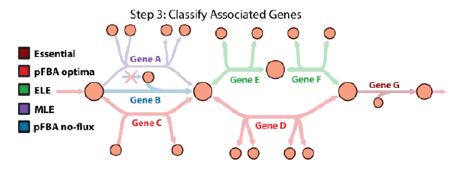

                                                                                  Figure 3: Gene classes retrieved through pFBA.

Some genes may not fit in any of this 5 categories. These genes will be saved in a vetor called 'remainingGenes'.

OptimaGenes = [];
restGenes = pFBAfluxGenes;
for i = 1:length(RxnOptima)
    listGenes = find(RxnGMat(RxnOptima(i), :));
    for n = 1:length(listGenes)
        pos = find(pFBAfluxGenes==listGenes(n));
        if pos 
            OptimaGenes = [OptimaGenes; model.genes(pFBAfluxGenes(pos))];
            restGenes(pos,1) = 0;
        end 
    end
end
OptimaGenes = unique(OptimaGenes);
restGenes(restGenes==0) = [];    

ELEGenes = [];
restGenes2 = restGenes;
for i = 1:length(RxnELE)
    listGenes = find(RxnGMat(RxnELE(i), :));
    for n = 1:length(listGenes)
        pos = find(restGenes==listGenes(n));
        if pos 
            ELEGenes = [ELEGenes; model.genes(restGenes(pos))];
            restGenes2(pos, 1) = 0;
        end 
    end
end
ELEGenes = unique(ELEGenes);
restGenes2(restGenes2==0) = [];

MLEGenes = [];
finalRemainingGenes = restGenes2;
for i = 1:length(RxnMLE)
    listGenes = find(RxnGMat(RxnMLE(i),:));
    for n = 1:length(listGenes)
        pos = find(restGenes2==listGenes(n));
        if pos 
            MLEGenes = [MLEGenes; model.genes(restGenes2(pos))];
            finalRemainingGenes(pos, 1) = 0;
        end 
    end
end
MLEGenes = unique(MLEGenes);
finalRemainingGenes(finalRemainingGenes==0) = []; 

remainingGenes = [];
for n = 1:length(finalRemainingGenes)
        remainingGenes = [remainingGenes; model.genes(finalRemainingGenes(n))];
end

## **Pri****nt results:**

essential_genes
OptimaGenes
ELEGenes
MLEGenes
pFBAnoFluxGenes

## TIMING

The tutorial runs in a few minutes.

## References

[1] Lewis et al. Omic data from evolved E. coli are consistent with computed optimal growth from genome-scale models. *Mol Syst Biol. *6:390 (2010).

[2] Orth, J., Fleming, R.M., Palsson B. Ø. Reconstruction and Use of Microbial Metabolic Networks: the Core Escherichia coli Metabolic Model as an Educational Guide. *EcoSal Plus.* 4(1) (2010).

[3] Thiele, I., et al. A community-driven global reconstruction of human metabolism. *Nat Biotechnol*. 31(5):419-425 (2013).